+++1.2.1

clear

% help plot
% lookfor plot
% doc

1.2.2

clear

a = [1 2 3]; 
b = a.';  
c = a * b; 
c  

c = 14

c = a.* a; 
c 

c =      1     4     9


With ";", the output will not be printed.

1.2.3

clear

x = rand(10,1);
[mean,stdev] = stat(x)

mean = 0.6239

stdev = 0.3281

1.3

1.3.1


$$\int_0^{2\pi \;} {\left(\sin \;5t\right)}^2 \textrm{dt}=\frac{1}{2}\int_0^{2\pi \;} {\left(\sin \;5t\right)}^2 +{\left(\cos \;5t\right)}^2 \textrm{dt}=\pi$$


clear

num = 1000

num = 1000

x = linspace(0, 2*pi, num); 
y = (sin(5*x)).^2;           

dx = x(2) - x(1); 
integral_1 = sum(y) * dx 

integral_1 = 3.1416


$$\int_0^1 e^t \textrm{dt}=e-1$$


clear

num = 1000

num = 1000

x = linspace(0,1,num);
y = exp(x);
dx = x(2)-x(1);
integral_2 = sum(y)*dx

integral_2 = 1.7201

1.3.2

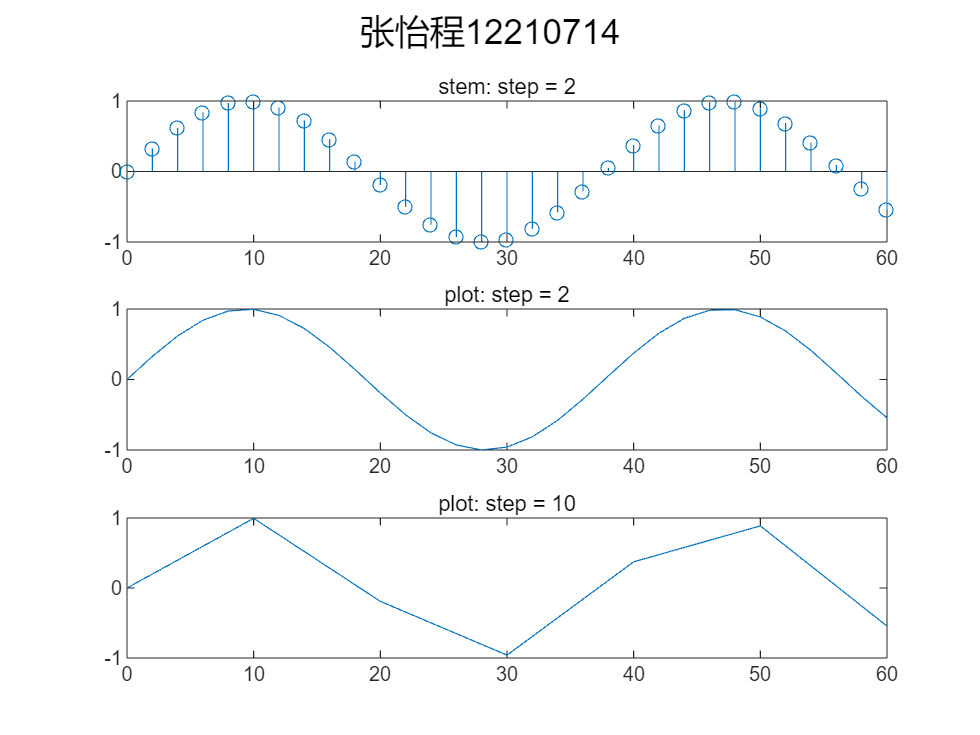

clear

n=0:2:60;
y=sin(n/6);
subplot(311);
sgtitle('张怡程12210714')
stem(n,y);
title('stem: step = 2')

n1=0:2:60;
z=sin(n1/6);
subplot(312)
plot(n1,z);
title('plot: step = 2')
n2=0:10:60;
w=sin(n2/6);
subplot(313)
plot(n2,w)
title('plot: step = 10')

The first plot is a nice reconstruction of the original function, while the second one failed to do it because the samples are too few.

1.3.3


$$\int_0^{2\pi \;} {\left(\sin \;5t\right)}^2 \textrm{dt}$$


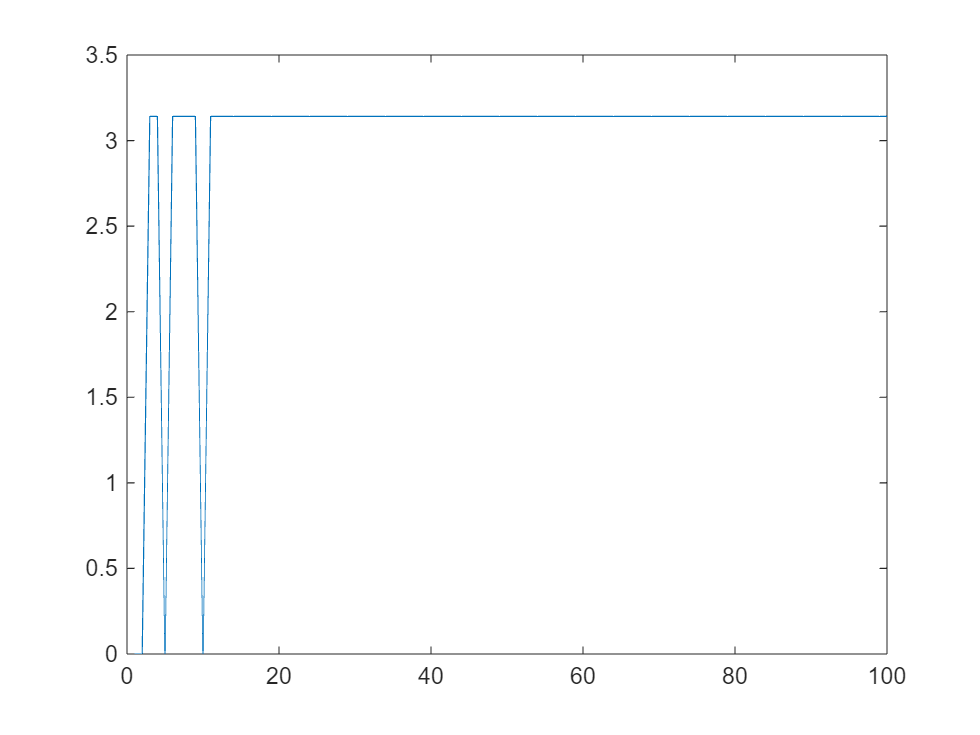

clear

% I_100 = integ1(100)
I_100 = arrayfun(@integ1, 1:100);
plot(I_100)

% I_50 = integ1(50)
% I_10 = integ1(10)
% I_5 = integ1(5)


$$\int_0^1 e^t \textrm{dt}$$


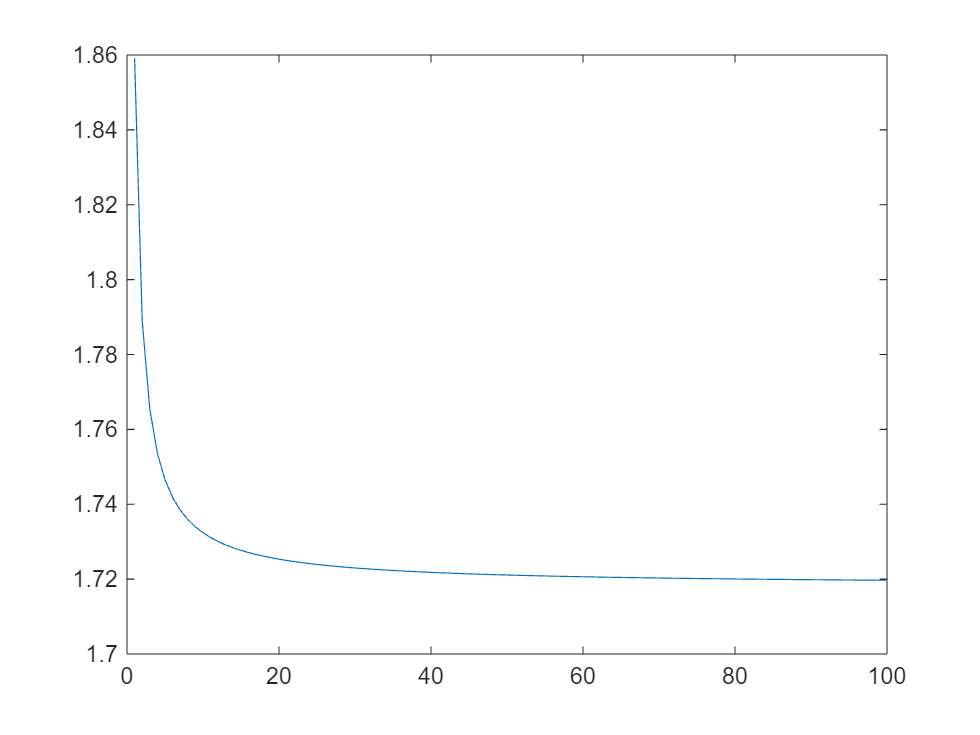

clear

% J_100 = integ2(100)
J_100 = arrayfun(@integ2, 1:100);
plot(J_100)

1.4

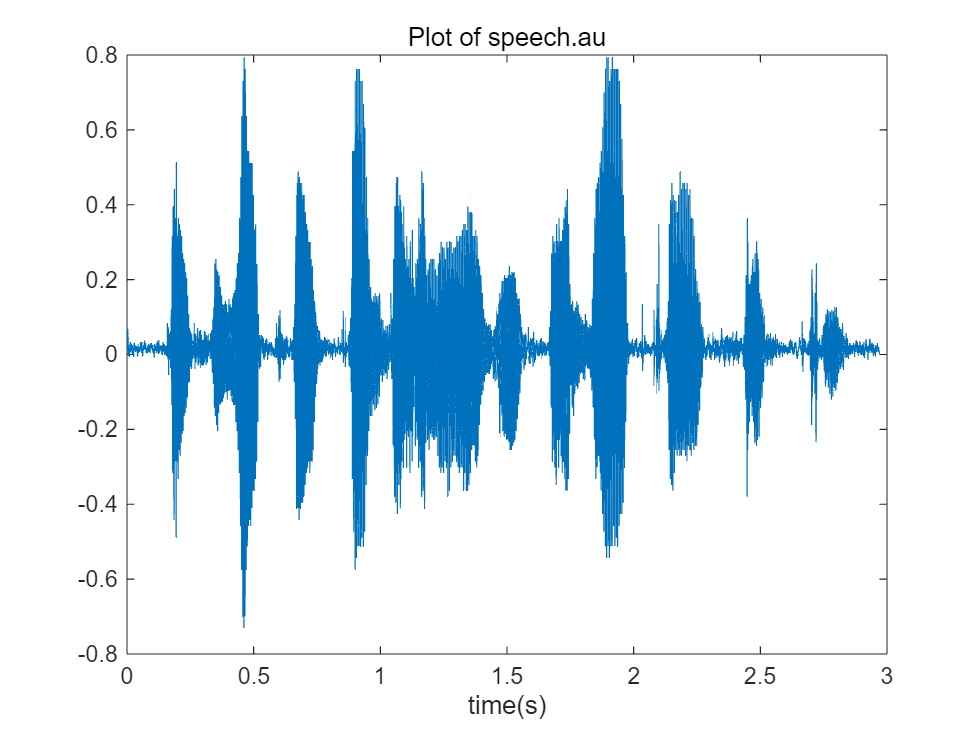

clear
figure

[y,fs]=audioread('data/speech.au');
t = (1:length(y))./fs;
plot(t,y)
title('Plot of speech.au')
xlabel('time(s)')

% sound(y,fs)

1.5


$$\textrm{sinc}\left(x\right)=\frac{\sin \left(\pi x\right)\;}{\pi x}$$


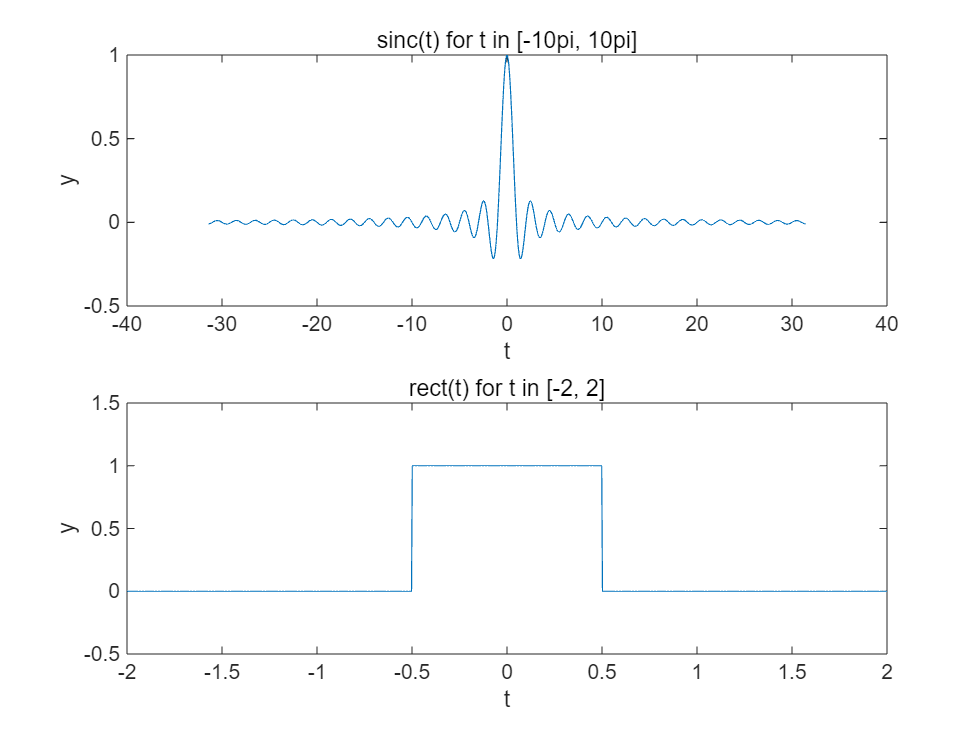

clear
figure

N = 1000;
[t,y] = sinc(N);
subplot(211)
% orient('tall')
plot(t,y)
xlabel('t');ylabel('y')
title('sinc(t) for t in [-10pi, 10pi]')

[t,y]=rect(N);
subplot(212)

plot(t,y)
xlabel('t');ylabel('y')
ylim([-0.5,1.5])
title('rect(t) for t in [-2, 2]')

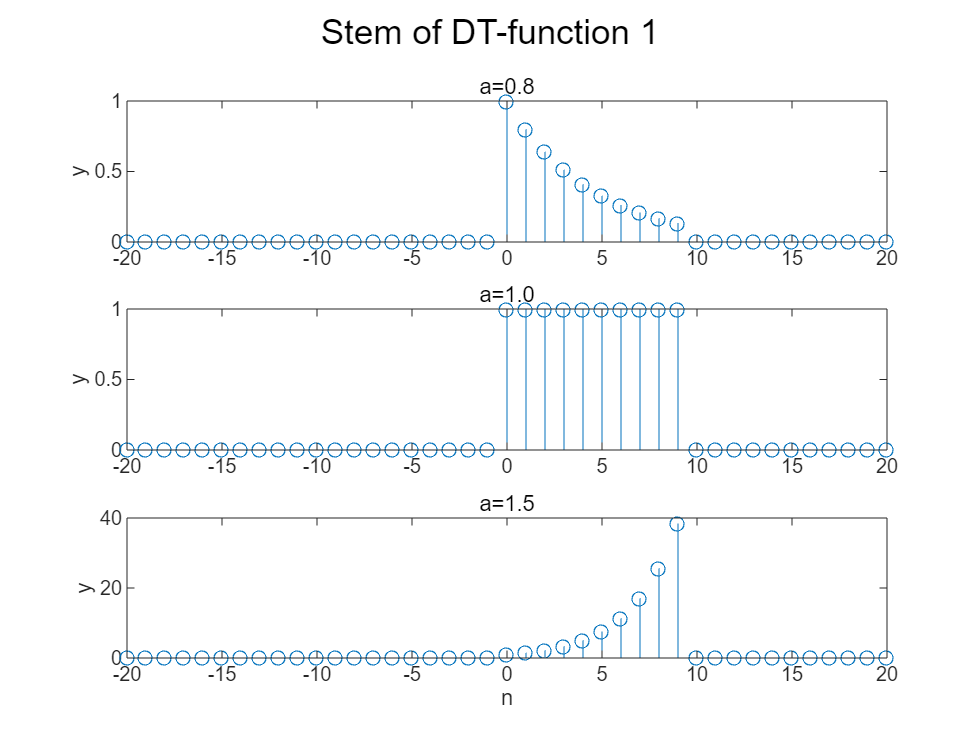

clear
figure

[n1,y1]=dtfunc1(0.8);
[n2,y2]=dtfunc1(1.0);
[n3,y3]=dtfunc1(1.5);

subplot(311)
orient('tall')
stem(n1,y1)
title('a=0.8')
ylabel('y')

subplot(312)
stem(n2,y2)
title('a=1.0')
ylabel('y')

subplot(313)
stem(n3,y3)
title('a=1.5')
xlabel('n')
ylabel('y')

sgtitle('Stem of DT-function 1')

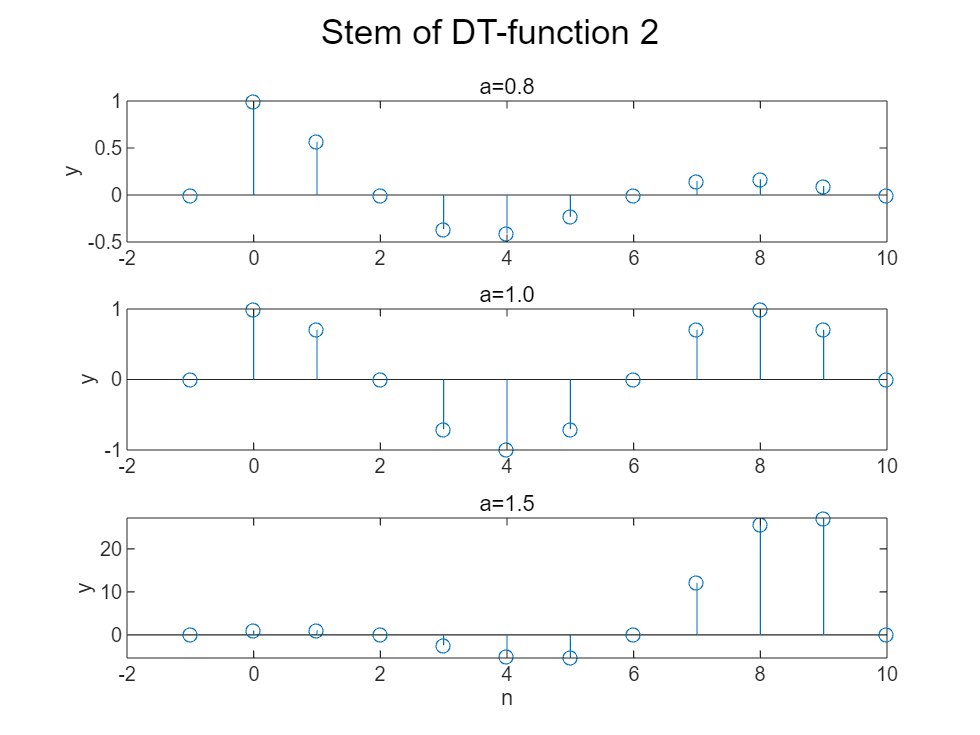

clear
figure

[n1,y1]=dtfunc2(0.8);
[n2,y2]=dtfunc2(1.0);
[n3,y3]=dtfunc2(1.5);

subplot(311)
orient('tall')

stem(n1,y1)
title('a=0.8')
ylabel('y')

subplot(312)
stem(n2,y2)
title('a=1.0')
ylabel('y')

subplot(313)
stem(n3,y3)
title('a=1.5')
xlabel('n')
ylabel('y')

sgtitle('Stem of DT-function 2')

1.6

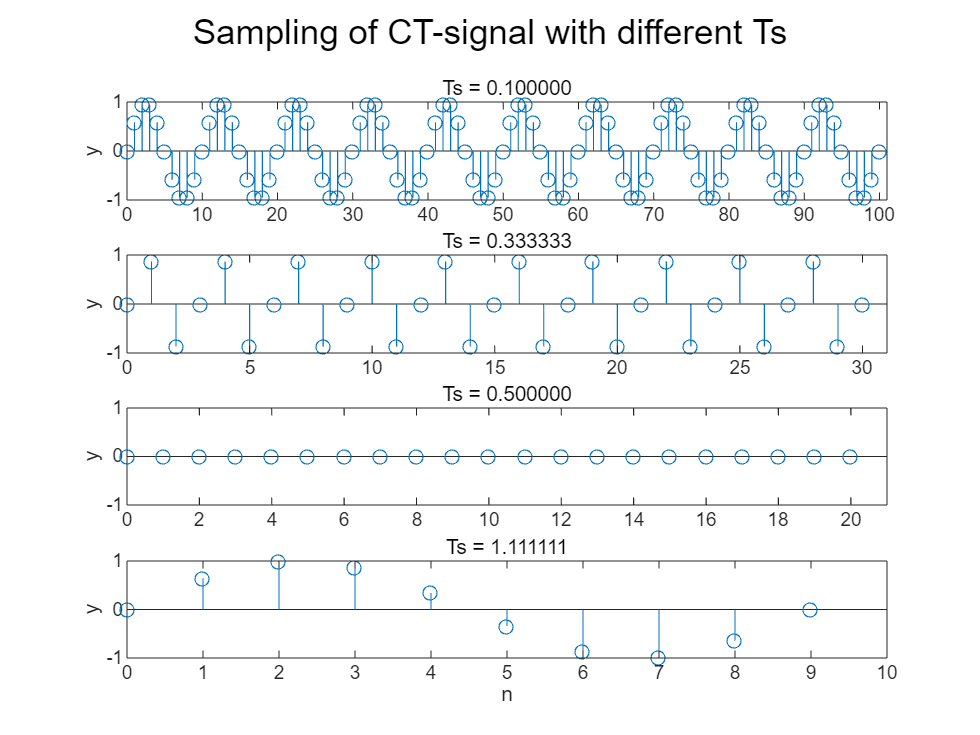

clear;figure

subplot(411)
sampfunc(1/10)
subplot(412)
sampfunc(1/3)
subplot(413)
sampfunc(1/2)
subplot(414)
sampfunc(10/9)
xlabel('n')
sgtitle('Sampling of CT-signal with different Ts')

Ts = 1/10 performs a good reconstruction of the signal.

Ts = 1/3 fails to reconstruct the sinusoidal appearance. However, the frequency is preserved.

Ts = 1/2 fails to reconstruct the signal. The values happen to be all zero.

Ts = 10/9 undersamples the signal. The reconstructed frequency is lower than the original ones.

Therefore, to reconstruct the signal, a rather high sampling frequency is needed.

1.7

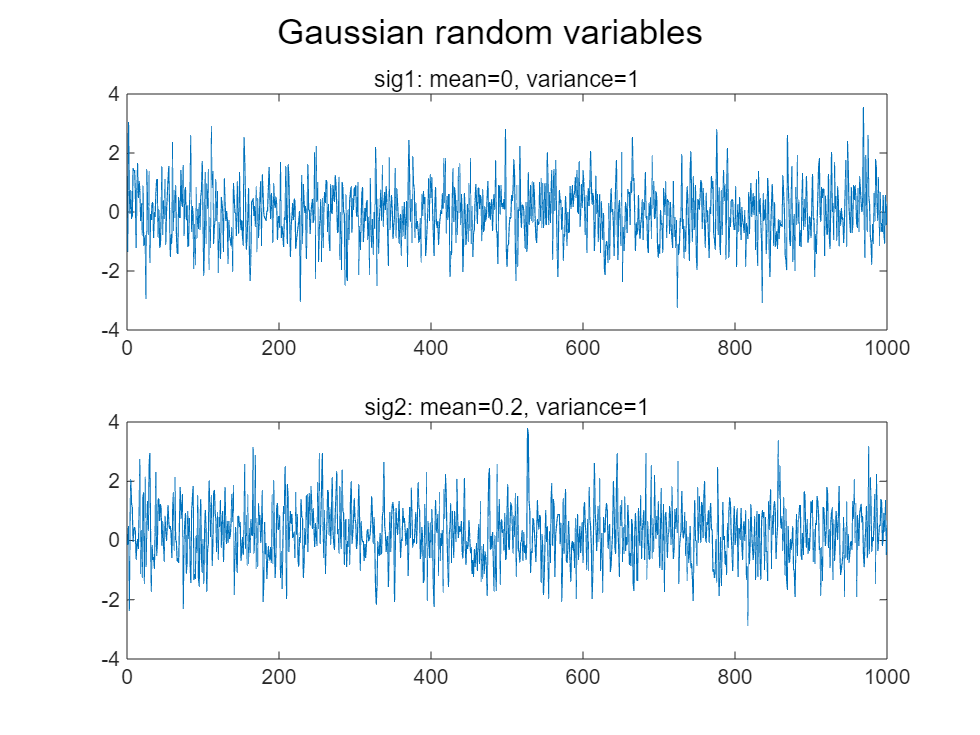

clear;figure

sig1 = randn(1000,1)*1+0;
sig2 = randn(1000,1)*1+0.2;

subplot(211)
plot(sig1)
title('sig1: mean=0, variance=1')
subplot(212)
plot(sig2)
title('sig2: mean=0.2, variance=1')
sgtitle('Gaussian random variables')

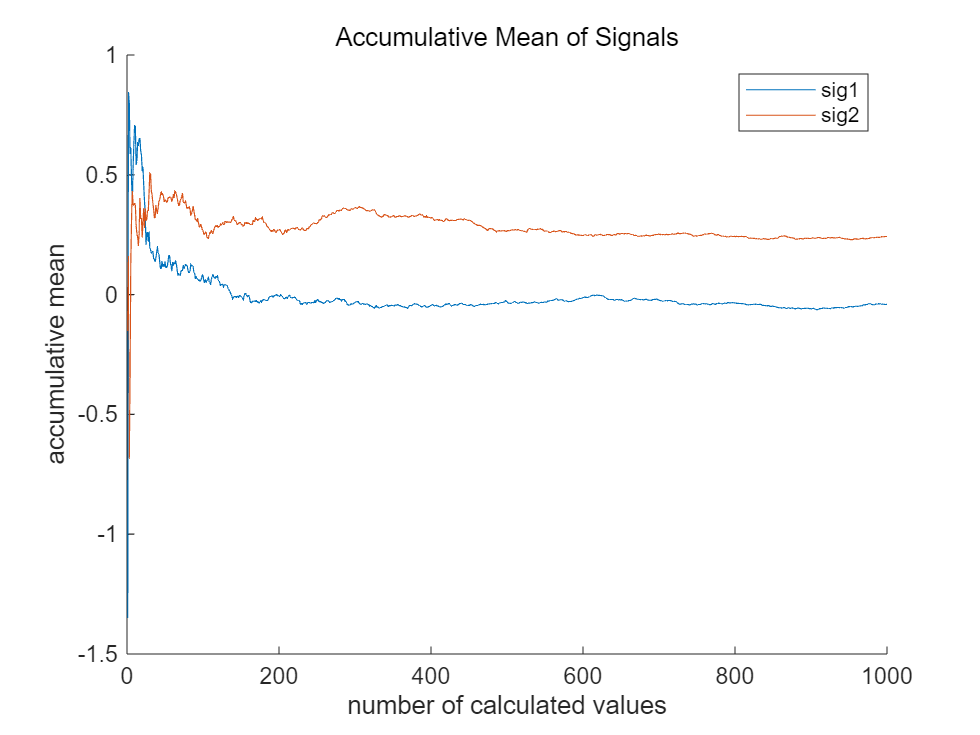

figure;hold on
n=1000;
ave1 = ave(sig1(1:n));
ave2 = ave(sig2(1:n));

plot(ave1)
plot(ave2)

legend('sig1', 'sig2')
title('Accumulative Mean of Signals')
xlabel('number of calculated values')
ylabel('accumulative mean')

As n increases, the average values approximate the mean of the Gaussian distribution. This is due to the Law of Large Numbers.

1.8

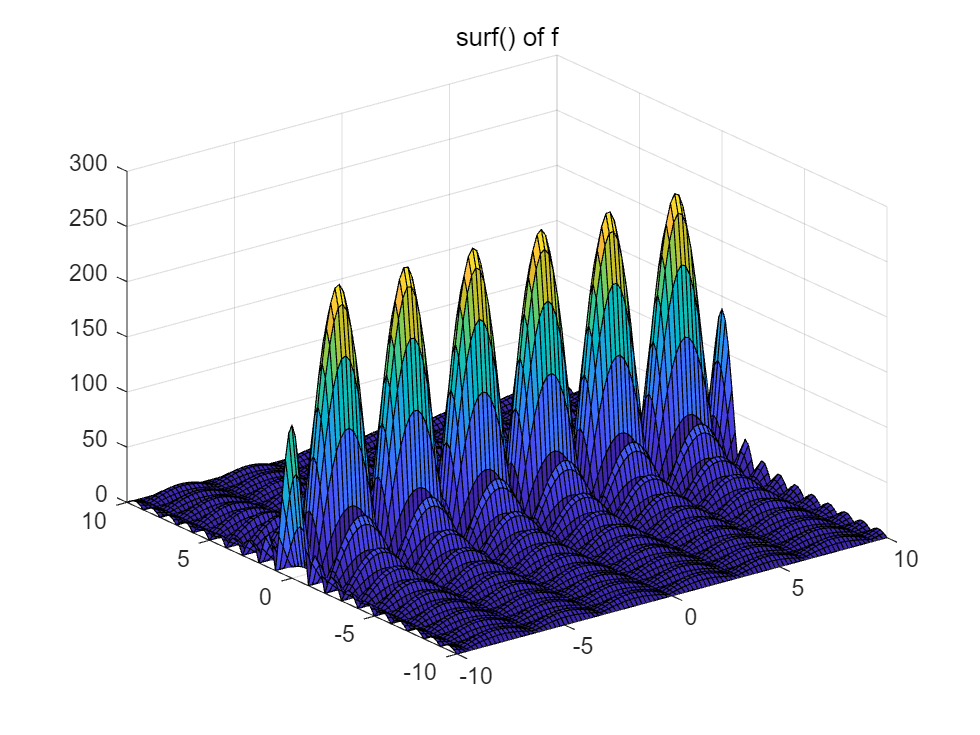

clear;figure

f=func2d();
[X, Y]=meshgrid((-50:50)*0.2);
surf(X,Y,f)
title('surf() of f')

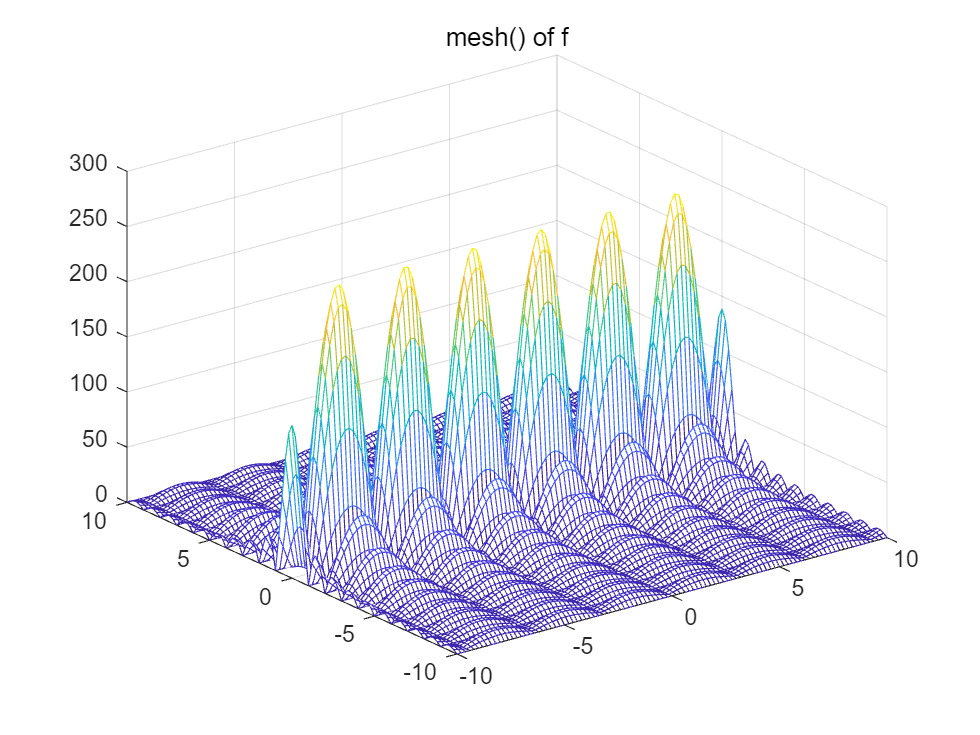

figure
mesh(X,Y,f)
title('mesh() of f')

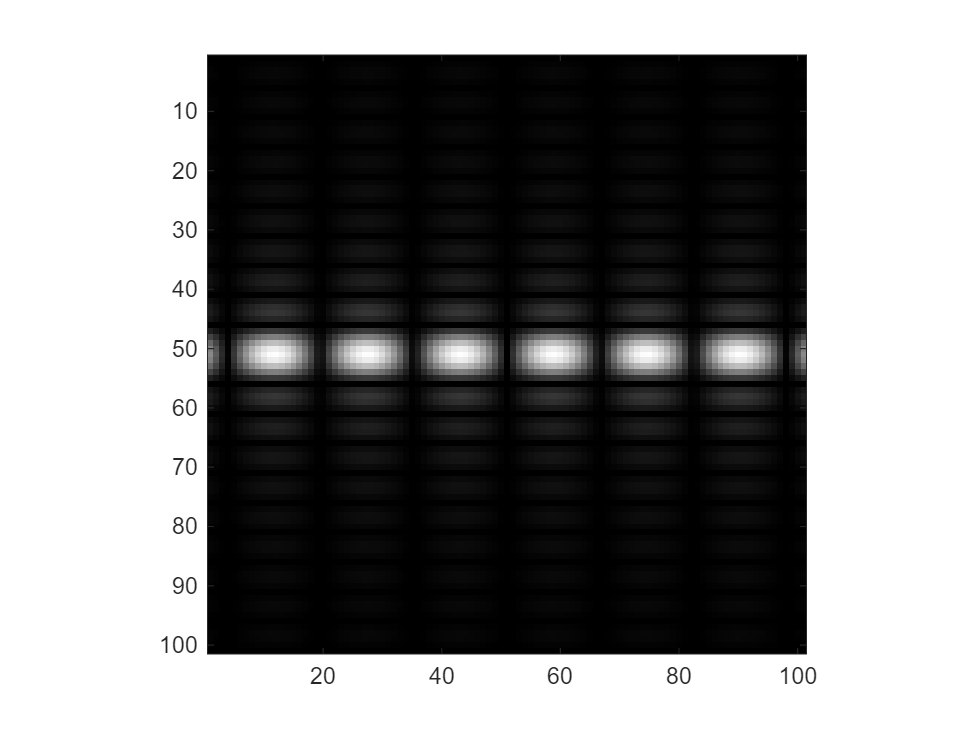

image(f)
colormap(gray(256))
axis('image')

The mesh() and surf() provide 3D graphs for visualization, which is more intuitive and alows better perception of trends and shapes. The image() provide 3D visualization that is less intuitive. However, less computation time is needed and accurate perception can be obtained from the coordinates which don't endure perspective transformation.